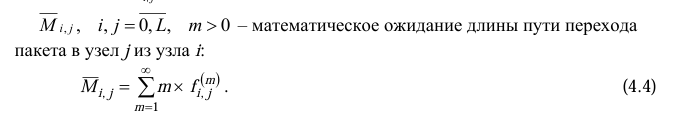

% Функция для вычисления математического ожидания длины пути
function exp_length = expected_path_length(P, i, j, epsilon)
    m = 1;
    exp_length = 0;
    while true
        prob = first_passage_probability(P, i, j, m);
        exp_length = exp_length + m * prob;
        if prob <= epsilon
            break;
        end
        m = m + 1;
    end
end